% Clear the workspace
clear
addpath('./functions/');

%  Load an image
filepath = "images\starfish_17.jpg"

filepath = "images\starfish_17.jpg"

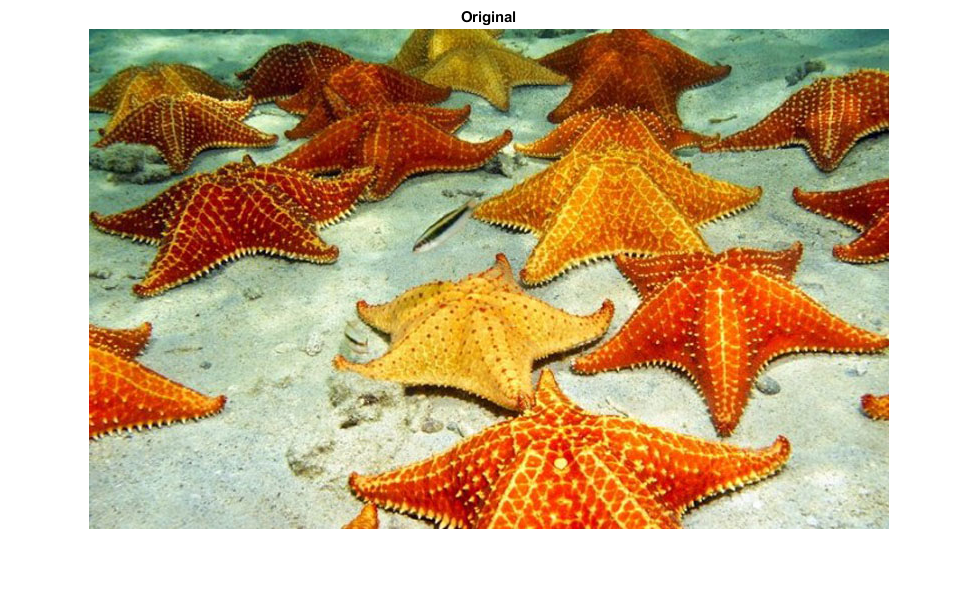

oIm = imread(filepath);
imshow(oIm);
title("Original");


imArea = numel(oIm(:,:,1))

imArea = 400000

maxBlobSize = imArea * 0.025%0.015

maxBlobSize = 10000

minBlobSize = imArea * 0.0015%0.006

minBlobSize = 600

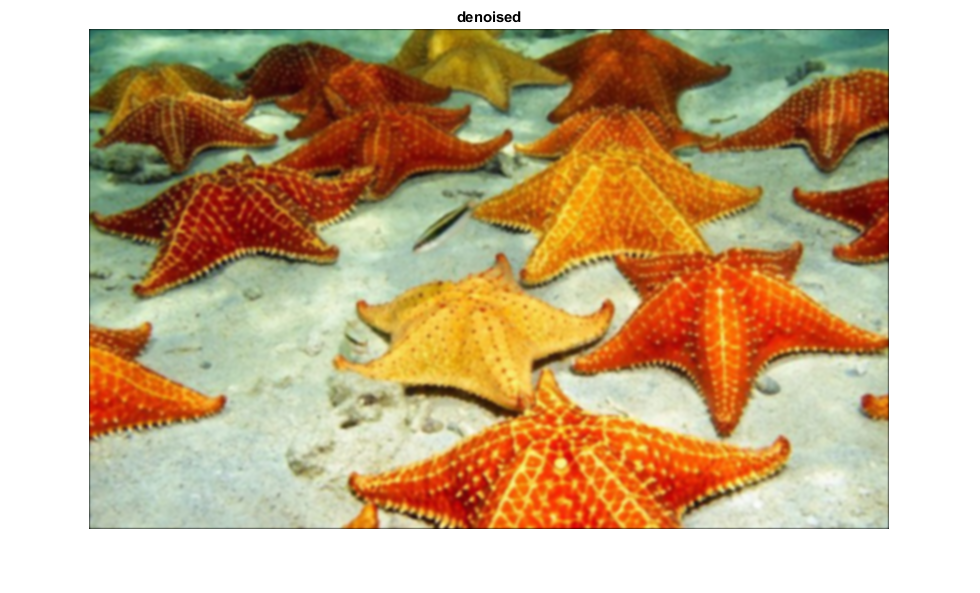


% Orientate landscape for morphological ops.
[h,w,d] = size(oIm);
if (h > w)
    oIm = rot90(oIm);
    oIm = rot90(oIm);
    oIm = rot90(oIm);
end

% % Denoise and enhance.
im = oIm;
[c1,c2,c3] = imsplit(im);
c1 = medfilt2(c1);
c2 = medfilt2(c2);
c3 = medfilt2(c3);
im = cat(3, c1,c2,c3);
im = MeanFilter(im, 3);
% im = DenoiseIsolated(im, "medianfilter");
im = Denoise1(im);

imshow(im);
title("denoised");

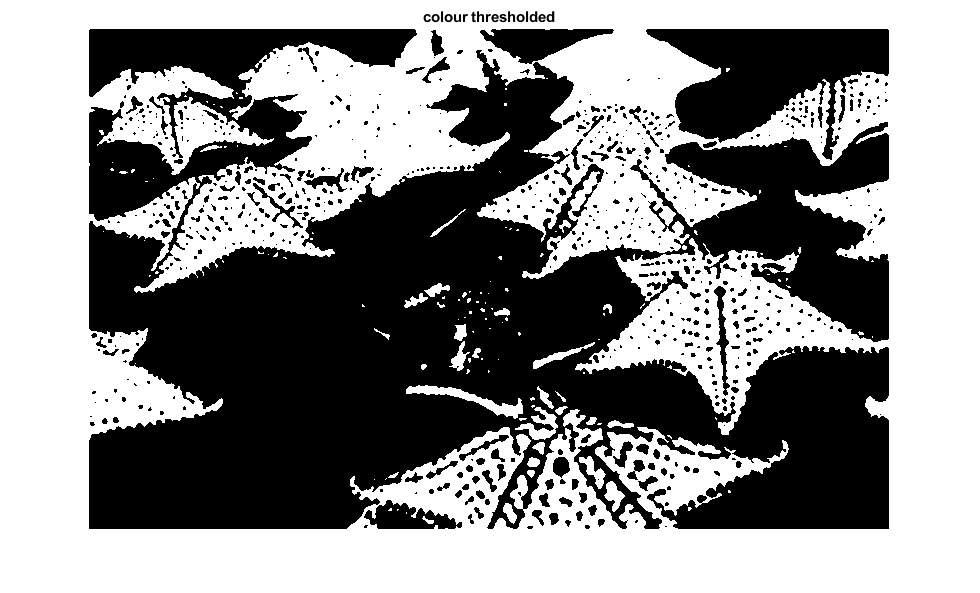


if(IsLowContrast(im))
    % Enhance the contrast of cluttered and low-contrast images.
    [c1,c2,c3] = imsplit(im);
    c1 = adapthisteq(c1);
    c2 = adapthisteq(c2);
    c3 = adapthisteq(c3);
    im = cat(3, c1,c2,c3);
    imshow(im);
    title("contrast enhanced");
end

% Threshold the image in hsv and get a rough mask with candidate blobs.
% mask = logical(HSVInvertedThresh(im));
mask = logical(ThresholdRGB(im));
imshow(mask);
title("colour thresholded");


% If the image is primarily dark, invert the mask to make objects the
% foreground.
% if (IsDark(im))
%     mask = ~mask;
% end

% CONDITIONALLY MORPH BASED ON NOISE VALUE
% se = strel('line', 2, 0);
% mask = imerode(mask, se);
% imshow(mask);
% title("erode")

% % Remove large blobs (preserve small "noise" in case they are fragments)
% properties_table = regionprops('table', mask, 'all');
% areas = properties_table.Area;
% minBlobArea = min(areas)
% maxBlobArea = max(areas)
% medianBlobArea = mean2(areas)
% stdBlobArea = std2(areas)
% if ((stdBlobArea * 1.5) > maxBlobSize)
%     maxBlobSize = maxBlobArea;
% end
% mask = bwareafilt(mask, [0 maxBlobSize]);
% imshow(mask);
% title("bwareafilt initial");
% 
% mask = imfill(mask, 'holes');
% imshow(mask);
% title("holes filled");

% % Morph
noiseLevel = mean2(GetNoiseLevel(im))

noiseLevel = 2.0667e-04

if(noiseLevel > 0.7)
   
    se = strel('disk', 2);
    mask = imopen(mask, se);
    imshow(mask);
    se = strel('line', 4, 0);
    mask = imclose(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imerode(mask, se);
    se = strel('line', 4, 45);
    mask = imclose(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imerode(mask, se);
    se = strel('line', 4, 90);
    mask = imclose(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imerode(mask, se);
    se = strel('line', 4, 135);
    mask = imclose(mask, se);
    imshow(mask);
    
    se = strel('line', 3, 0);
    mask = imdilate(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imclose(mask, se);
    se = strel('line', 3, 45);
    mask = imdilate(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imclose(mask, se);
    se = strel('line', 3, 90);
    mask = imdilate(mask, se);
    imshow(mask);
    se = strel('diamond', 1);
    mask = imclose(mask, se);
    se = strel('line', 3, 135);
    mask = imdilate(mask, se);
    imshow(mask);

end


% % Remove large blobs (preserve small "noise" in case they are fragments)
% properties_table = regionprops('table', mask, 'all');
% areas = properties_table.Area;
% minBlobArea = min(areas)
% maxBlobArea = max(areas)
% medianBlobArea = mean2(areas)
% stdBlobArea = std2(areas)
% if ((stdBlobArea * 1.5) > maxBlobSize)
%     maxBlobSize = maxBlobArea;
% end
% mask = bwareafilt(mask, [0 maxBlobSize]);
% imshow(mask);
% title("bwareafilt initial");


% Remove noise
% finalMask = bwareafilt(mask, [minBlobSize maxBlobSize]);
% imshow(finalMask);
% title("bwareafilt denoise")
% If we removed all items, reduce small threshold until objects found or
% % max attempts tried.
% finalMask = mask;
% [~, nCC] = bwlabel(finalMask);
% attempts = 0;
% maxAttempts = 5;
% while (nCC == 0 && attempts < maxAttempts)
%     attempts = attempts + 1
%     minBlobSize = imArea * (0.0015 * attempts)
%     finalMask = bwareafilt(mask, [minBlobSize maxBlobSize]);
%     imshow(finalMask);
%     title("bwareafilt denoise")
%     [~, nCC] = bwlabel(finalMask);
% end

finalMask = mask;
maskall = MSERIsolateStarfish(finalMask);

ans = 1×2 single row vector
  452.2690  397.3327


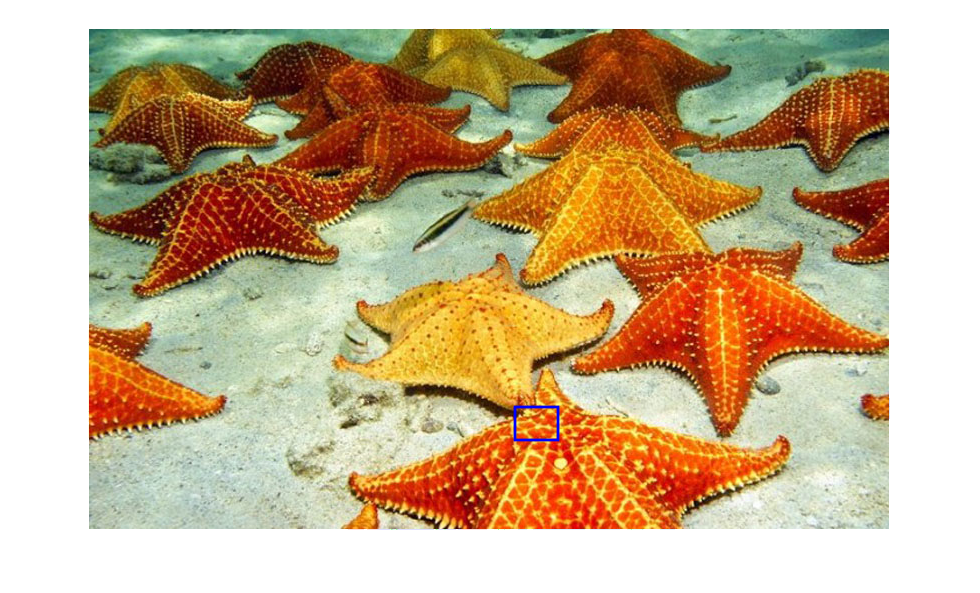


% DRAW FINAL ROIS
DrawROIs(oIm, maskall);


[~, n] = bwlabel(maskall)

n = 1

function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %

function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;
    
    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
    %     if (noiseValue > 30)
    %         disp("Switching mode");
    %         method = "meanfilter";
    %         repeat = true;
    %     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %


function t = statxture(f, scale)
%STATXTURE Computes statistical measures of texture in an image.
%   T = STATXURE(F, SCALE) computes six measures of texture from an
%   image (region) F. Parameter SCALE is a 6-dim row vector whose
%   elements multiply the 6 corresponding elements of T for scaling
%   purposes. If SCALE is not provided it defaults to all 1s.  The
%   output T is 6-by-1 vector with the following elements:
%     T(1) = Average gray level
%     T(2) = Average contrast
%     T(3) = Measure of smoothness
%     T(4) = Third moment
%     T(5) = Measure of uniformity
%     T(6) = Entropy

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.5 $  $Date: 2004/11/04 22:33:43 $

if nargin == 1
    scale(1:6) = 1;
else % Make sure it's a row vector.
    scale = scale(:)';
end

% Obtain histogram and normalize it.
p = imhist(f);
p = p./numel(f);
L = length(p);

% Compute the three moments. We need the unnormalized ones
% from function statmoments. These are in vector mu.
[~, mu] = statmoments(p, 3); % Hole for the first variable.

% Compute the six texture measures:
% Average gray level.
t(1) = mu(1);
% Standard deviation.
t(2) = mu(2).^0.5;
% Smoothness.
% First normalize the variance to [0 1] by
% dividing it by (L-1)^2.
varn = mu(2)/(L - 1)^2;
t(3) = 1 - 1/(1 + varn);
% Third moment (normalized by (L - 1)^2 also).
t(4) = mu(3)/(L - 1)^2;
% Uniformity.
t(5) = sum(p.^2);
% Entropy.
t(6) = -sum(p.*(log2(p + eps)));

% Scale the values.
t = t.*scale;
end


function [v, unv] = statmoments(p,  n)
%STATMOMENTS Computes statistical central moments of image histogram.
%   [W, UNV] = STATMOMENTS(P, N) computes up to the Nth statistical
%   central moment of a histogram whose components are in vector
%   P. The length of P must equal 256 or 65536.
%
%   The program outputs a vector V with V(1) = mean, V(2) = variance,
%   V(3) = 3rd moment, . . . V(N) = Nth central moment. The random
%   variable values are normalized to the range [0, 1], so all
%   moments also are in this range.
%
%   The program also outputs a vector UNV containing the same moments
%   as V, but using un-normalized random variable values (e.g., 0 to
%   255 if length(P) = 2^8). For example, if length(P) = 256 and V(1)
%   = 0.5, then UNV(1) would have the value UNV(1) = 127.5 (half of
%   the [0 255] range).

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.3 $  $Date: 2003/05/24 22:43:02 $

Lp = length(p);
if (Lp ~= 256) && (Lp ~= 65536)
    error('P must be a 256- or 65536-element vector.');
end
G = Lp - 1;

% Make sure the histogram has unit area, and convert it to a
% column vector.
p = p/sum(p); p = p(:);

% Form a vector of all the possible values of the
% random variable.
z = 0:G;

% Now normalize the z's to the range [0, 1].
z = z./G;

% The mean.
m = z*p;

% Center random variables about the mean.
z = z - m;

% Compute the central moments.
v = zeros(1, n);
v(1) = m;
for j = 2:n
    v(j) = (z.^j)*p;
end

if nargout > 1
    % Compute the uncentralized moments.
    unv = zeros(1, n);
    unv(1)=m.*G;
    for j = 2:n
        unv(j) = ((z*G).^j)*p;
    end
end
end
